# **Session 4: Improvement of the PID controllers implemented in practice 3**

The practices of the Automatic Control subject consist in the study of a servomechanism of angular positioning (LJ Technical Systems) controlled by a PC. The laboratory sessions P1 and P2 focus on the experimental analysis of the temporal and frequency responses of the system, respectively. Sessions P3 and P4 are dedicated to the design of PID controllers. Finally, in session P5 controllers will be designed in the frequency domain.

**OBJECTIVE: To design a I-P controller for the velocity output so that the closed loop system has a zero steady-state error. Design a I-PD controller for the position output shaft of the plant studied in previous sessions so that the closed loop system meets certain specifications.**

**In this session the student has to:**

- **Design a I-P and a I-PD by pole placement.**

- **Experimentally verify the control systems designed.**

% Alternate between the experiment data and the directory Results
% If you want to use the data in the directory Results = false
% If you want to use your own data = true
useExperimentalData = false;

# Exercise 14: Design and implementation of a I-P controller by pole placement.

As we saw on practice 3, when designing a PI controller with a first-order plant they have as response with a system with two poles and a zero. The zero, has a negative effect on the dynamics of the system, usually making it a little faster than desired, that is why we obtained a small overshoot. To eliminate the effect of zero, the following alternative architecture of introducing proportional and integral actions is proposed.

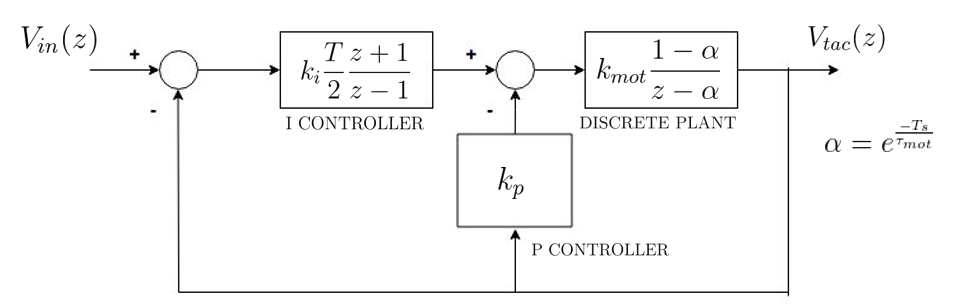

This control structure takes the name of IP controller, and as can be seen, the integral action is fed back from the error, while the proportional part is fed back from the output. As the proportional action of the IP controller doesn’t see the reference, so the response of the closed loop system to a step input of a IP controller is smoother than the one with the PI. As has been done in P3, we want to design an I-P speed control that makes the temporary response to a step input does not present overshoots and that the settling time (with the 2% criterion) is 0.8 seconds. For the simulation of the digital I-P controller, open and execute the model P4_Ex14a.slx. To check with the engine, open and execute model P4_Ex14b.slx.

% Plant
K0=0.82;
tau0=0.26;

% Sampling time
Ts=0.01;

% Specifications
xi=1;
ts_2=0.8; % settling time with %2 criterion
Tdes=ts_2/4;
wn=5.8/(xi*ts_2);

% Controller design
Zdes=exp(-Ts/Tdes);
alpha=exp(-Ts/tau0);
beta=-2*exp(-Ts*xi*wn)*cos(wn*Ts*sqrt(1-xi^2));
gamma=exp(-2*Ts*xi*wn);

Ki_star=(gamma-alpha+beta+(alpha+1))/(2*K0*(1-alpha));
Ki=(2/Ts)*Ki_star;
Kp=((beta+alpha+1)/(K0*(1-alpha)))-Ki_star;

To design the controller, the following steps have been followed. First, the plant has been digitized with a zero order holder and a discrete I-P controller (digitized by the trapezoidal approach) has been chosen.


$$\mathrm{motor}:G\left(z\right)=k_{\mathrm{mot}} \frac{1-\alpha }{z-\alpha }\;\;\;\;\;\;\;\;\;\mathrm{donde}\;\;\;\;\;\;\;\;\;\;\;\;\alpha =e^{-\frac{T_s }{\tau_0 }}$$



$$\textrm{PI}\;\mathrm{controller}:\textrm{PI}\left(z\right)=k_p +k_i \frac{T_s }{2}\frac{z+1}{z-1}=k_p +k_i^* \frac{z+1}{z-1}\;\;\;\;\;\;\textrm{donde}\;\;\;\;k_i^* =k_i \frac{T_s }{2}$$


In this case, the closed loop transfer function:


$$\mathrm{l}c\left(z\right)=\frac{\mathrm{IP}\left(z\right)G\left(z\right)}{1+\textrm{IP}\left(z\right)G\left(z\right)}=\frac{k_{\textrm{mot}} k_i^* \left(z+1\right)\left(1-\alpha \right)}{\left(z-1\right)\left(z-\alpha \right)+k_{\textrm{mot}} \left(k_p +k_i^* \right)\left(z+\frac{k_i^* -k_p }{k_i^* +k_p }\right)\left(1-\alpha \right)}$$


In the case of PI, the closed-loop transfer function was:


$$\mathrm{l}c\left(z\right)=\frac{\mathrm{PI}\left(z\right)G\left(z\right)}{1+\mathrm{PI}\left(z\right)G\left(z\right)}=\frac{k_{\textrm{mot}} k_i^* \left(z+\frac{k_i^* -k_p }{k_i^* +k_p }\right)\left(1-\alpha \right)}{\left(z-1\right)\left(z-\alpha \right)+k_{\textrm{mot}} \left(k_p +k_i^* \right)\left(z+\frac{k_i^* -k_p }{k_i^* +k_p }\right)\left(1-\alpha \right)}$$


As we can see, when fixing the poles through the controller's gains in the case of the PI control structure, the closed-loop zero is automatically fixed. However, if we analyze the zero of the I-P architecture, we can see how the zero is fixed in z=-1.  

Since the closed loop denominator is the same as that obtained in practice 3, the equations used to tune the controller parameters are exactly the same as those used for the PI controller.


$$\begin{array}{l}
\mathrm{eq}\;\mathrm{real}:z^2 +\left\lbrack \left(k_p +k_i^* \right)k_{\mathrm{mot}} \left(1-\alpha \right)-\left(\alpha +1\right)\right\rbrack z+\alpha +k_{\mathrm{mot}} \left(k_i^* -k_p \right)\left(1-\alpha \right)=0\\
\mathrm{eq}\;\mathrm{ideal}:z^2 -2e^{-T_s \xi \omega_n } \mathrm{cos}\left(\omega_n T_s \sqrt{1-\xi^2 }\right)z+e^{-2T_s \xi \omega_n } 
\end{array}$$


With which, the tuning equations would be:


$$\begin{array}{l}
k_p =\frac{-\left(-2e^{-T_s \xi \omega_n } \mathrm{cos}\left(\omega_n T_s \sqrt{1-\xi^2 }\right)+e^{-2T_s \xi \omega_n } +1\right)}{T_s \;k_{\mathrm{mot}} \;\left(\alpha -1\right)}\\
k_i =\frac{-2e^{-T_s \xi \omega_n } \mathrm{cos}\left(\omega_n T_s \sqrt{1-\xi^2 }\right)+e^{-2T_s \xi \omega_n } +1}{2{\;k}_{\mathrm{mot}} \;\left(\alpha -1\right)}-\frac{\alpha -2e^{-T_s \xi \omega_n } \mathrm{cos}\left(\omega_n T_s \sqrt{1-\xi^2 }\right)+1}{k_{\mathrm{mot}} \;\left(\alpha -1\right)}
\end{array}$$


The ideal and real responses of the I-P controller can be seen in the following image.

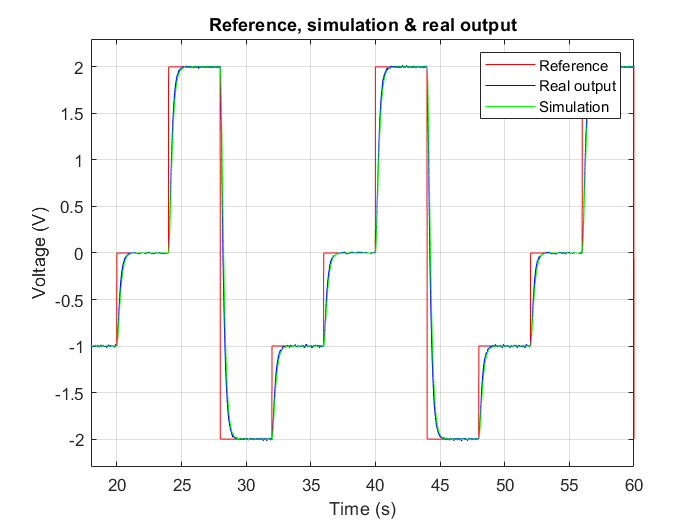

% Draw motor's response
if useExperimentalData
    % Use Simulink
    addpath([pwd filesep 'IPvel']);
    open IP_experimental.slx;
    run IP_experimental.slx;
else
    FileName   = 'IP_ideal.mat';
    cd('..')
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac3'];
    File       = fullfile(FolderName, FileName);
    load(File);  
    
    FileName   = 'IP_real.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac3'];
    File       = fullfile(FolderName, FileName);
    load(File);  
end

figure
plot(IP_ideal.time,[IP_ideal.signals.values(:,1,:)],'r')
hold on; grid on;
plot(IP_real.time,[IP_real.signals.values(:,2,:)],'b')
plot(IP_ideal.time,[IP_ideal.signals.values(:,2,:)],'g')
xlim([18 60]); ylim([-2.3 2.3]);
xlabel('Time (s)');
ylabel('Voltage (V)');
title('Reference, simulation & real output');
legend('Reference','Real output','Simulation');

As can be analyzed, the two answers are practically the same and with this, we can say, the real system meets the desired specifications.

# Exercise 15: Design and implementation of a I-PD controller by pole placement.

As we have seen in practice 3, when designing a PID controller with a second-order plant, we obtained a closed-loop system with 4 poles and 3 zeros. In order to design a PID controller where the specifications are met, two main modifications must be made, the first one, adding a new parameter to the controller in order to fix the four poles of the system, and the second, modifying the structure to eliminate the effect of the zeros

With which, the new controller, will have the following structure:


$$\textrm{PI}\mathrm{D}\;\mathrm{controller}:\mathrm{P}\textrm{ID}\left(z\right)=k_p +k_i^* \frac{z+1}{z-1}+k_d^* \;\frac{z-1}{z+\alpha }\;\;\;\;\textrm{donde}\;\;\;\;k_i^* =k_i \frac{T_s }{2}\;\;y\;k_d^* =\frac{k_d }{T_s }$$


To eliminate the effect of zeros, the following alternative architecture is proposed to introduce the proportional, integral and derivative actions.

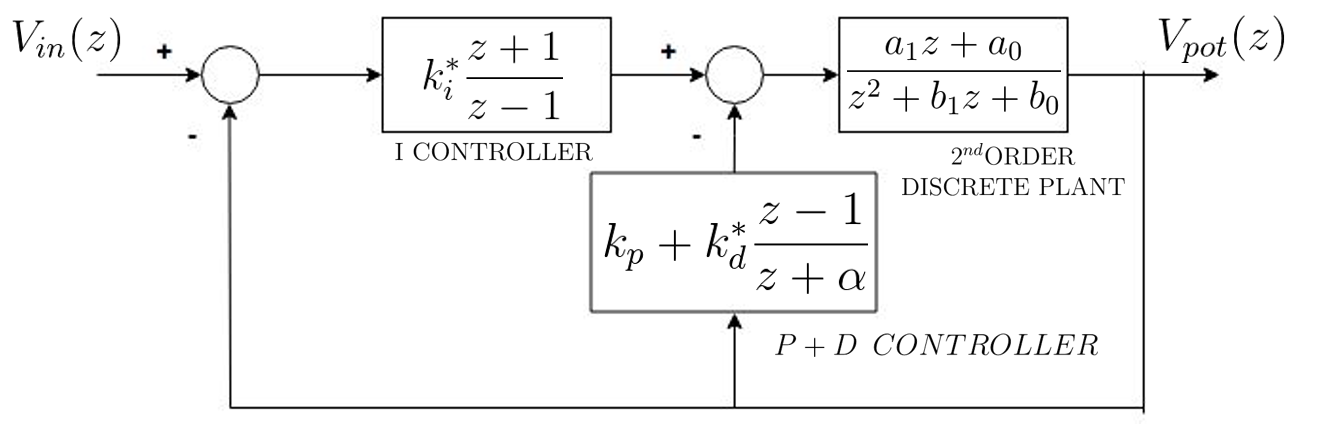

This structure takes the name of I-PD controller, and as can be seen, the integral action is fed back from the error, while the proportional and derivative actions are fed back directly from the output.

In this exercise we want to design a I-PD position control that makes the temporary response to a step input present an overshoot of 80% and an oscillation frequency of 0.5 Hz.

Take the sampling period Ts equal to 0.01s. Determine the value of $k_p$,$\;k_i$ y $k_d$ y $\alpha$. 

% Plant's parameters 
K0=0.82/0.017;
tau0=0.26;
N=9;
Kpot=1.62;

% Sampling time
Ts=0.01;

% Desired control specifications
Sp=80; % overshoot
Fd=0.5; % frequency

% Continuous second order poles that will meet the specifications
wd=2*pi*Fd ;
xi=sqrt((log(Sp/100))^2/(pi^2+log(Sp/100)^2))

xi = 0.0709

wn=wd/ sqrt(1-xi^2)

wn = 3.1495

s1=-xi*wn+j*wd

s1 = -0.2231 + 3.1416i

s2=-xi*wn-j*wd

s2 = -0.2231 - 3.1416i

% Discrete second order poles that will meet the specifications
p1=exp(Ts* s1 )

p1 = 0.9973 + 0.0313i

p2=exp(Ts* s2 )

p2 = 0.9973 - 0.0313i

% Insert the third and fourth poles
p3=0.8

p3 = 0.8000

p4=0.8

p4 = 0.8000

% Discrete plant transfer function 
Ptas=tf([K0*(1/N)*Kpot],[tau0,1,0]);
Ptaz=c2d(Ptas,Ts,'zoh');

% Coefficients of the denominator and enumerator 
[Nz ,Dz]= tfdata(Ptaz,'v')

Nz =          0    0.0016    0.0016


Dz =     1.0000   -1.9623    0.9623


a1=Nz(2);
a0=Nz(3);
b1=Dz(2);
b0=Dz(3);

% Definition of matrices A and B
A=[1 a1 0 0; ...
   b1-1 a0 a1 0; 
   b0-b1 0 a0 a1; 
  -b0 0 0 a0] ;
b=[-b1+1-p1-p2-p3-p4; 
   -b0+b1+p1*p2-(-p1-p2)*p3-(-p1-p2-p3)*p4; 
   b0-p1*p2*p3-(p1*p2-(-p1-p2)*p3)*p4; 
   p1*p2*p3*p4] ;

% Controller 
x=inv(A)*b ; 

alpha=x(1)

alpha = -0.6472

c2=x(2)

c2 = 9.0217

c1=x(3)

c1 = -17.8623

c0=x(4)

c0 = 8.8526

A2=[1 1 1; alpha-1 alpha+1 -2; -alpha alpha 1];
B2=[c2;c1;c0];

x2=inv(A2)*B2;

kp = x2(1)

kp = 0.3994

ki = (2/Ts)*x2(2)

ki = 3.4247

kd = Ts*x2(3)

kd = 0.0861

In the case of practice 3, the transfer function obtained had the following structure:


$$\mathrm{cl}\left(z\right)=\frac{a_1 \left(k_p +k_i^* {+k}_d^* \right)z^3 +\left\lbrack a_1 \left(k_i^* -k_p -2k_d^* \right)+a_0 \left(k_p +k_i^* {+k}_d^* \right)\right\rbrack z^2 +\left\lbrack a_1 k_d^* +a_0 \left(k_i^* -k_p -2k_d^* \right)\right\rbrack z+a_0 k_d^* }{z^4 +\left(-1+k_i^* a_1 +b_1 +k_d^* a_1 +k_p a_1 \right)z^3 +\left(-b_1 -k_p a_1 +k_p a_0 +b_0 -2k_d^* a_1 +k_i^* a_0 +k_i^* a_1 +k_d^* a_0 \right)z^2 +\left(k_i^* a_0 -b_0 -2k_d^* a_0 -k_p a_0 +k_d^* a_1 \right)z+k_d^* a_0 }$$


As we can see, when fixing the poles through the controller's gains, the closed-loop zeros were automatically set. The expressions of the closed loop poles are the following:


$$z_{1,2} =\frac{-\left(k_i^* -k_p -2k_d^* \right)\pm \sqrt{-4k_d^* \left(k_p +k_i^* {+k}_d^* \right)+{\left(k_i^* -k_p -2k_d^* \right)}^2 }}{2\left(k_p +k_i^* {+k}_d^* \right)}\;,\;z_3 =\frac{a_0 }{a_1 }$$


In the case of the I-PD however, the closed-loop transfer function is as follows:


$$\textrm{cl}\left(z\right)=\frac{k_i^* \left(z+1\right)\left(a_1 z+a_0 \right)\left(z+\alpha \right)}{z^4 +\left(b_1 -1+\alpha +k_i^* a_1 +k_d^* a_1 +k_p a_1 \right)z^3 +\left(b_0 -b_1 +b_1 \alpha -\alpha +k_p a_1 \left(\alpha -1\right)+k_p a_0 -2k_d^* a_1 +k_i^* a_0 +k_i^* a_1 \left(\alpha +1\right)+k_d^* a_0 \right)z^2 +\left(-b_0 +b_0 \alpha -b_1 \alpha +k_p a_0 \left(\alpha -1\right)-k_p a_1 \alpha +k_i^* a_0 \left(\alpha +1\right)+k_i^* a_1 \alpha -2k_d^* a_0 +k_d^* a_1 \right)z+k_d^* a_0 +k_i^* a_0 \alpha -k_p a_0 \alpha -b_0 \alpha }$$


As we can see, in this case, the zeros are fixed in:


$$z_1 =-1,z_2 =-\alpha ,z_3 =\frac{-a_0 }{a_1 }$$


To obtain the tuning equations, however, as we can see, the obtained equation is not linear, so we will replace the controller with the canonical form of the PID and then we will relate them to the implemented IPD.

The canonical transfer function of the PID with four parameters has the following form:


$$\textrm{PI}\mathrm{D}\;\mathrm{controller}:\mathrm{P}\textrm{ID}\left(z\right)=\frac{c_2 z^2 +c_1 z+c_0 }{\left(z-1\right)\left(z+\alpha \right)}$$



$$\textrm{second}\;\textrm{order}\;\textrm{plant}:G\left(z\right)=\frac{a_{1\;} z+a_0 }{z^2 +b_{1\;} z+b_0 }$$


Whereby the denominator of the closed loop transfer function with the canonical controller takes the form:


$$\textrm{Den}\left(z\right)=z^4 +\left\lbrack \alpha -1+b_1 +c_2 a_1 \right\rbrack z^3 +\left\lbrack \left(b_1 -1\right)\alpha -b_1 +b_0 +a_1 c_1 +a_0 c_2 \right\rbrack z^2 +\left\lbrack \left(b_0 -b_1 \right)\alpha -b_0 +a_0 c_1 +c_0 a_1 \right\rbrack z+c_0 a_0 -\alpha b_0$$


The polynomial is of fourth order, which will have four poles and the characteristic equation will be:


$$\begin{array}{l}
\mathrm{Den}\left(z\right)=\left(z-p_1 \right)\left(z-p_2 \right)\left(z-p_3 \right)\left(z-p_4 \right)=z^4 +\left(-p_1 {-p}_2 -p_3 -p_4 \right)z^3 \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;+\left(p_1 p_2 -\left({-p}_1 -p_2 \right)p_3 -\left(-p_1 -p_2 -p_3 \right)p_4 \right)z^2 \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;+\left({-p}_1 p_2 p_3 -\left(p_1 p_2 -\left({-p}_1 -p_2 \right)p_3 \right)p_4 \right)z+p_1 p_2 p_3 p_4 
\end{array}$$


As it is a fourth order system and four unknowns, equaling the coefficients and representing it in matrix form, the closed loop system would be:


$$\left\lbrack \begin{array}{cccc}
1 & a_1  & 0 & 0\\
b_1 -1 & a_0  & a_1  & 0\\
b_0 -b_1  & 0 & a_0  & a_1 \\
-b_0  & 0 & 0 & a_0 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\alpha \\
c_2 \\
c_1 \\
c_0 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
1-b_1 -p_1 {-p}_2 -p_3 -p_4 \\
b_1 -b_0 +p_1 p_2 -\left({-p}_1 -p_2 \right)p_3 -\left(-p_1 -p_2 -p_3 \right)p_4 \\
b_0 {-p}_1 p_2 p_3 -\left(p_1 p_2 -\left({-p}_1 -p_2 \right)p_3 \right)p_4 \\
p_1 p_2 p_3 p_4 
\end{array}\right\rbrack$$


This linear system is easily solvable using MATLAB. The equation is $A\;x=b$, where $A$ is a matrix $n\;x\;n$ y $b$ is a column vector with $n$ elements, so, $x=\mathrm{inv}\left(A\right)·b$.

Finally, to obtain the parameters $k_p {,\;k}_i \;\mathrm{and}\;k_d$ we will obtain the relationship between our controller and the canonical model.

Our controller can also be represented as follows:


$$\mathrm{P}\textrm{ID}\left(z\right)=\frac{\left(k_p +k_i^* +k_d^* \right)z^2 +\left(k_p \left(\alpha -1\right)+k_i^* \left(\alpha +1\right)-2k_d^* \right)z-k_p \alpha +k_i^* \alpha +k_d^* }{\left(z-1\right)\left(z+\alpha \right)}$$


With which, equaling the coefficients and representing it in matrix form:


$$\left\lbrack \begin{array}{ccc}
1 & 1 & 1\\
\alpha -1 & \alpha +1 & -2\\
-\alpha  & \alpha  & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
k_p \\
k_i^* \\
k_d^* 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
c_2 \\
c_1 \\
c_0 
\end{array}\right\rbrack$$


As has been done previously, this system is easily soluble by means of MATLAB, being the solution $x=\textrm{inv}\left(A\right)·b$.

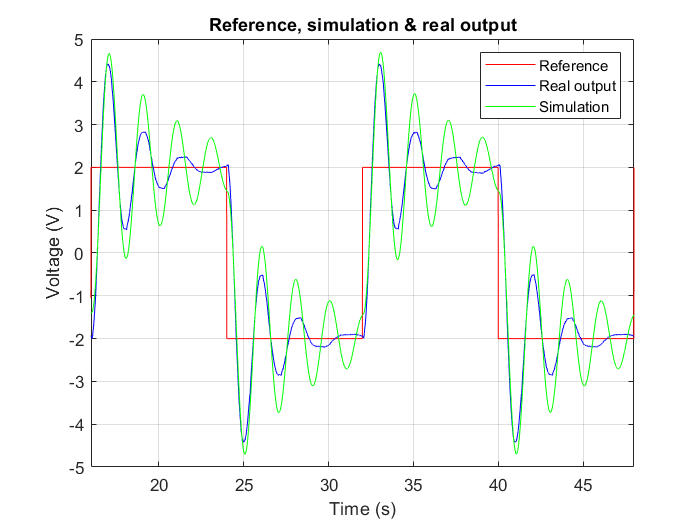

% Draw motor's response
if useExperimentalData
    % Use Simulink
    addpath([pwd filesep 'IPDpos']);
    open IPD_real_ideal.slx;
    run IPD_real_ideal.slx;
else
    FileName   = 'IPD_real_ideal.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac4'];
    File       = fullfile(FolderName, FileName);
    load(File);   
end

figure
plot(IPD_real_ideal.time,[IPD_real_ideal.signals.values(:,1,:)],'r')
hold on; grid on;
plot(IPD_real_ideal.time,[IPD_real_ideal.signals.values(:,2,:)],'b')
plot(IPD_real_ideal.time,[IPD_real_ideal.signals.values(:,3,:)],'g')
xlim([16 48]);
xlabel('Time (s)');
ylabel('Voltage (V)');
title('Reference, simulation & real output');
legend('Reference','Real output','Simulation');

As we can see, in this case, the specifications are met in the ideal case (simulation with the model of the plant), but when controlling the actual plant with this architecture, we can see that, although the controller is able to control the plant, the responses are quite different. This is because the model of the plant does not faithfully represent the real plant, since there are non modelled dynamics.